# APPLADE Training main 

This .mlx file is the main file to train a DNN that is to be used in the proposed method, **APPLADE**.

clear
close all
clc

addpath(genpath("Tools"))
addpath("Models")

## Load Dataset

You can use any dataset for training / validation. 

adsTrain = audioDatastore(fullfile('Dataset\Train\'),'IncludeSubfolders',true);
adsTrain = shuffle(adsTrain);

% Confirm the number of data for training.
disp(['# of data for training: ', num2str(length(adsTrain.Files))])

# of data for training: 5300



adsValid = audioDatastore(fullfile('Dataset\Valid\'),'IncludeSubfolders',true);
adsValid = shuffle(adsValid);

% Confirm the number of data for validation.
disp(['# of data for validation: ', num2str(length(adsValid.Files))])

# of data for validation: 23


## Set Parameters

param.Fs = 16e3;
param.L = 16384; % 256*64

% Set the parameters for DGT.
param.winLen = 1024;
param.shiftRatio = 4;
param.shiftLen = round(param.winLen/param.shiftRatio);
param.fftLen = param.winLen;
dgtParamGPU = initializeDGT(param);

DGT initialized



% To make a folder to store the trained parameters.
dt = datetime('now');
D = datestr(dt, 'yyyy-mmm-dd-HH')

D = '2022-Jan-22-19'

mkdir(['Trained_Networks/',D])

% Set the parameters for Adam.
numEpochs = 200;
miniBatchSize = 4;
iteration = 0;
averageGrad = gpuArray(single([]));
averageSqGrad = gpuArray(single([]));
initialLearnRate = gpuArray(single(1e-4));
gradDecay = gpuArray(single(0.9));
sqGradDecay = gpuArray(single(0.999));
decay = gpuArray(single(0));

% Set the parameters for DNN structure.
parameters = initializeModelParameters;

## Create Mini-batches

Pre-processing will be also defined and carried out.

T_mbq = minibatchqueue(adsTrain, 6,...
    'MiniBatchSize', miniBatchSize,...
    'MiniBatchFcn', @(x) preprocessMiniBatch(x,param,dgtParamGPU),...
    "OutputAsDlarray", [1, 1, 1, 1, 0, 0],...
    'OutputCast', {'single', 'single', 'single', 'single', 'single', 'single'},...
    'MiniBatchFormat', {'SSBC', 'SSBC', 'SSBC', 'SSBC', '', ''});

V_mbq = minibatchqueue(adsValid, 6,...
    'MiniBatchSize', miniBatchSize,...
    'MiniBatchFcn', @(x) preprocessMiniBatch(x,param,dgtParamGPU),...
    "OutputAsDlarray", [1, 1, 1, 1, 0, 0],...
    'OutputCast', {'single', 'single', 'single', 'single', 'single', 'single'},...
    'MiniBatchFormat', {'SSBC', 'SSBC', 'SSBC', 'SSBC', '', ''});

##  Prep for Displaying Figures

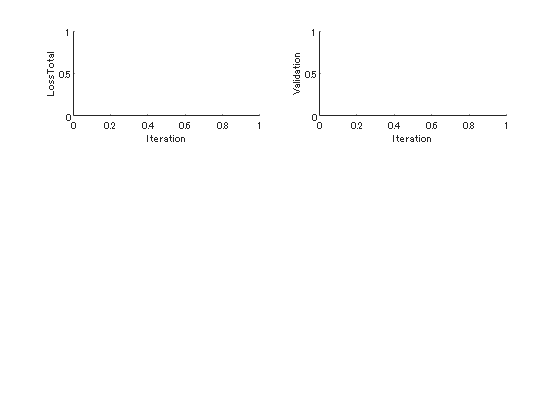

[Fig1, Fig2] = initializeFigure;

## Train

startT = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    % Shuffle data.
    shuffle(T_mbq);
    
    % Loop over mini-batches.
    while hasdata(T_mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        [Xre, Xim, Xcre, Xcim, x, Ridx] = next(T_mbq);
        
        % Get loss & gradients.
        [gradients, loss, figData] = dlfeval(@modelGradients, parameters,...
            Xre, Xim, Xcre, Xcim, x, Ridx, dgtParamGPU);
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);
                
        % Update the parameters with Adam.
        [parameters,averageGrad,averageSqGrad] = adamupdate(parameters,gradients,averageGrad,averageSqGrad,...
            iteration,learnRate,gradDecay,sqGradDecay);
        
        % Display the training progress & Calculate the validaton loss.
        % This part is run every 10 iterations.
        if ~mod(iteration,10)
            figData.vloss = calcValidationLoss(V_mbq, parameters, dgtParamGPU);
            updateFigures(figData, startT, Fig1, Fig2, iteration, epoch)
        end
        
    end
    
    % Store the current parameters every 10 epochs.
    if ~mod(epoch, 10)
        save(['DLNET/', D, '/parameters', num2str(epoch), 'Epochs.mat'], "parameters")
    end
    
end